# Battery testing, modelling, and state estimation - Parametrization and Validation of Battery Models

*Vaclav Knap*

Your tasks in this exercise are:

1) Process OCV measurement files and extract OCV model.

2) Determine RC parameters for an equivalent electrical circuit model (ECM) with 1RC element based on the provided pulse.

3) Implement ECM in discrete time.

4) Validate your model (the ECM using OCV and RC parameters that you derived) against dynamic discharge profile (DPP).

% Load provided ocv files.
ocv = cell(4, 1);
for i =1:4
    ocv{i}.data = readtable(sprintf('ocv_measurement/ocv_step%d.xlsx', i), Sheet='record');
end

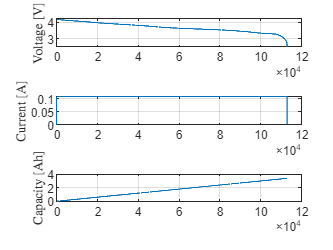

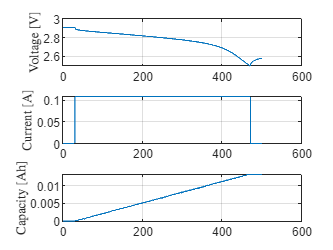

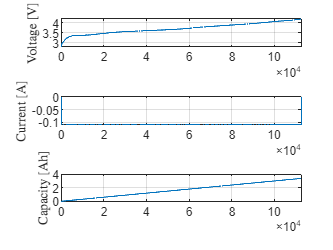

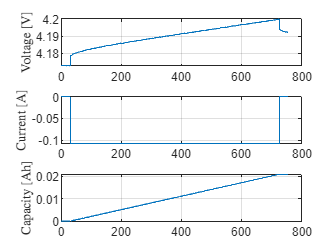

for i =1:4
    %extract variables
    [ocv{i}.Time, ocv{i}.Voltage, ocv{i}.Current, ocv{i}.Capacity] = extract_data(ocv{i}.data);

    % Find the spot where current drops and rest starts
    ocv{i}.Capacity(ocv{i}.data.StepID == 3) = ocv{i}.Capacity(find(ocv{i}.data.StepID == 3, 1) - 1);

    figure;
    tiledlayout(3,1, TileSpacing='compact');
    nexttile
    title(sprintf('File %d', i))
    plot(ocv{i}.Time, ocv{i}.Voltage);
    ylabel('Voltage [V]')
    grid on;
    nexttile
    plot(ocv{i}.Time, ocv{i}.Current);
    ylabel('Current [A]')
    grid on;
    nexttile
    plot(ocv{i}.Time, ocv{i}.Capacity);
    ylabel('Capacity [Ah]')
    grid on;
    
end

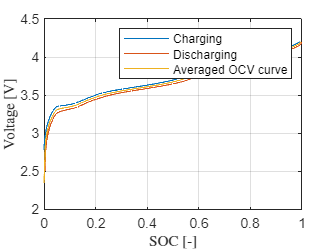

Q_charge = max(ocv{1}.Capacity) + max(ocv{2}.Capacity);
Q_discharge = max(ocv{3}.Capacity) + max(ocv{4}.Capacity);
Battery.Q = Q_discharge;
Battery.eta = Q_discharge / Q_charge;

charge = ocv{3};
charge.SOC = charge.Capacity / Q_charge;
discharge = ocv{1};
discharge.SOC = 1 - discharge.Capacity / Q_discharge;

figure
shared_SOC = (0:0.1:100) / 100;
[charge.SOC_unique, indices, ~] = unique(charge.SOC);
charge.Voltage_unique = charge.Voltage(indices);
U_charge_interpolated = interp1(charge.SOC_unique, charge.Voltage_unique, shared_SOC, 'linear', 'extrap');
[discharge.SOC_unique, indices, ~] = unique(discharge.SOC);
discharge.Voltage_unique = discharge.Voltage(indices);
U_discharge_interpolated = interp1(discharge.SOC_unique, discharge.Voltage_unique, shared_SOC, 'linear', 'extrap');

Battery.OCV.SOC = shared_SOC;
Battery.OCV.U = 0.5 * (U_charge_interpolated + U_discharge_interpolated);

plot(charge.SOC, charge.Voltage);
hold on;
%plot(shared_SOC, U_charge_interpolated);

plot(discharge.SOC, discharge.Voltage);
plot(Battery.OCV.SOC, Battery.OCV.U);
%plot(shared_SOC, U_discharge_interpolated);
grid on;
xlabel('SOC [-]');
ylabel('Voltage [V]');
legend('Charging', 'Discharging', 'Averaged OCV curve');
exportgraphics(gcf,'figures/ocv.eps');

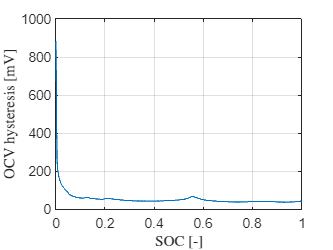


figure
plot(shared_SOC, 1000 * (U_charge_interpolated - U_discharge_interpolated));
grid on;
xlabel('SOC [-]');
ylabel('OCV hysteresis [mV]');



% Extract battery capacity, compute Coloumbic efficiency.
% Process data to obtain an OCV curve that you can use in your model (i.e.,
% OCV vs SOC characteristic).
% Plot OCV curve, together with measured cha/dch profiles in one graph.

% Load pulse data.
pulse_data = readtable('pulse/pulse.xlsx', Sheet='record');

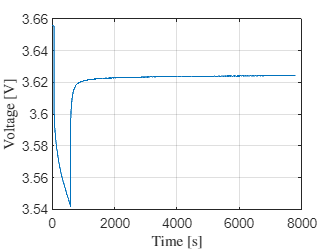

[Time, Voltage, Current, Capacity] = extract_data(pulse_data);
Capacity(pulse_data.StepID == 15) = Capacity(find(pulse_data.StepID == 15, 1) - 1);
figure;
plot(Time, Voltage)
grid on;
xlabel('Time [s]');
ylabel('Voltage [V]');

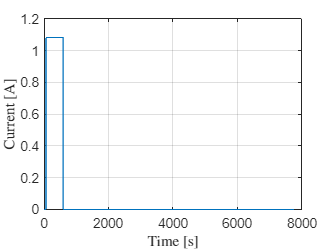

plot(Time, Current)
grid on;
xlabel('Time [s]');
ylabel('Current [A]');

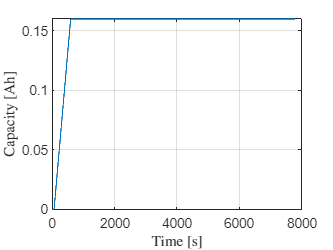

plot(Time, Capacity)
grid on;
xlabel('Time [s]');
ylabel('Capacity [Ah]');

% Process them according your needs (probably need to convert or create
% time vector). Remember to check current convention.
Ts = 1;
pulse_iddata = iddata([Voltage, Capacity], Current, Ts);
pulse_iddata.InputName = 'Current';
pulse_iddata.OutputName = {'Voltage', 'Capacity'};
pulse_iddata.InputUnit = 'A';
pulse_iddata.OutputUnit = {'V', 'Ah'};

%plot(pulse_iddata(:, 1, 1)); 
%plot(pulse_iddata(:, 2, 1)); 
Order.ny = 2;
Order.nu = 1;
Order.nx = 2;


param_R0.Name = 'R0';
param_R0.Unit = 'Ohm';
param_R0.Value = 0.04;
param_R0.Minimum = 0;
param_R0.Maximum = inf;
param_R0.Fixed = false;

param_R1.Name = 'R1';
param_R1.Unit = 'Ohm';
param_R1.Value = 0.1;
param_R1.Minimum = 0;
param_R1.Maximum = inf;
param_R1.Fixed = false;

param_C1.Name = 'C1';
param_C1.Unit = 'F';
param_C1.Value = 800;
param_C1.Minimum = 0;
param_C1.Maximum = inf;
param_C1.Fixed = false;

Parameters = [param_R0, param_R1, param_C1];
InitialStates = [0; 0];

SOC_init = interp1(Battery.OCV.U, Battery.OCV.SOC, Voltage(1))

SOC_init = 0.4768


model = idnlgrey('ECM_1RC_continuous', Order, Parameters, InitialStates, 0, FileArgument={Battery, SOC_init}, Name='Pulse experiment')


model =

Continuous-time nonlinear grey-box model defined by 'ECM_1RC_continuous' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p3, FileArgument)
    y(t) = H(t, u(t), x(t), p1, ..., p3, FileArgument) + e(t)

 with 1 input(s), 2 state(s), 2 output(s), and 3 free parameter(s) (out of 3).

Name: Pulse experiment

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%model = idnlgrey('ECM_1RC_continuous', Order, Parameters, InitialStates, 0)
set(model, 'InputName', 'Current', 'InputUnit', 'A', 'OutputName', {'Voltage', 'Capacity'}, 'OutputUnit', {'V', 'Ah'});

opt = nlgreyestOptions('Display', 'on');
model_new = nlgreyest(pulse_iddata, model, opt)


model_new =

Continuous-time nonlinear grey-box model defined by 'ECM_1RC_continuous' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p3, FileArgument)
    y(t) = H(t, u(t), x(t), p1, ..., p3, FileArgument) + e(t)

 with 1 input(s), 2 state(s), 2 output(s), and 3 free parameter(s) (out of 3).

Name: Pulse experiment

Status:                                                                             
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "pulse_iddata".
Fit to estimation data: [86.2;98.78]%                                               
FPE: 2.486e-13, MSE: 5.159e-06                                                      

Model Properties


Battery.R0 = model_new.Parameters(1).Value;
Battery.R1 = model_new.Parameters(2).Value;
Battery.C1 = model_new.Parameters(3).Value;
%PULSE_MODEL = pem(pulse_iddata, model)
% Find R0, R1, and C1 from the pulse. Use any of advance methods (e.g.,
% Lecture 4, slide 29 or 30). A guess is not enough (slide 28).

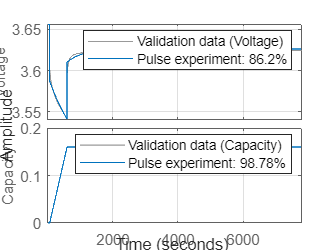

% Test your model that it behaves as expected.
% Use the pulse current as input.
% Compare measured and simulated output.
% Do simulation through for loop.
% Remember to initialize the model.
compare(pulse_iddata, model_new);
title('');
grid on
exportgraphics(gcf,'figures/pulse-compare.eps');

states = zeros(2, length(Time));
outputs = zeros(length(Time), 1);
inputs = Current';
x0 = [SOC_init; 0];
states(:, 1) = x0;

for k = 1:length(Time)-1
    [outputs(k), states(:, k+1)] = ECM_1RC(states(:, k), inputs(k), Battery);
end
[outputs(length(Time)), ~] = ECM_1RC(states(:, length(Time)), inputs(length(Time)), Battery);

rmse = calculate_error(Voltage, outputs) * 1e3

rmse = 2.2424

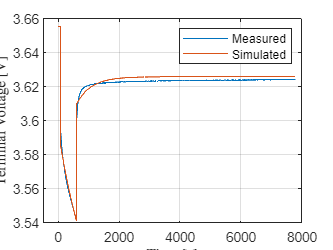


plot(Time, [Voltage, outputs]);
xlim([-500 8000])
grid on;
legend('Measured', 'Simulated');
xlabel('Time [s]');
ylabel('Terminal Voltage [V]')
exportgraphics(gcf,'figures/pulse-verification.eps');

% Load DDP measurement.
ddp_data = readtable('ddp/ddp.xlsx', Sheet='record');

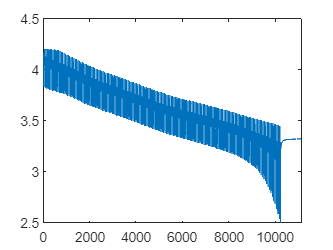

[Time, Voltage, Current, Capacity] = extract_data(ddp_data);
% Validate your model on DPP measurement.
% Compute RMSE for battery voltages.
figure
plot(Time, Voltage);

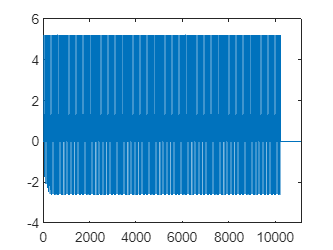

plot(Time, Current);

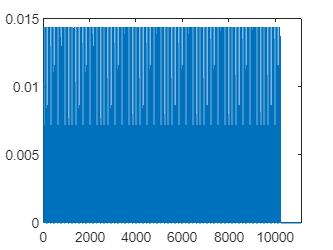

plot(Time, Capacity);


Ts = 1;
model_new.FileArgument{2} = 1;
ddp_iddata = iddata([Voltage, Capacity], Current, Ts);
ddp_iddata.InputName = 'Current';
ddp_iddata.OutputName = {'Voltage', 'Capacity'};
ddp_iddata.InputUnit = 'A';
ddp_iddata.OutputUnit = {'V', 'Ah'};
%compare(ddp_iddata, model_new);
%resid(ddp_iddata, model_new);
% Vomi comparison
states = zeros(2, length(Time));
outputs = zeros(length(Time), 1);
inputs = Current';
x0 = [1; 0];
states(:, 1) = x0;

for k = 1:length(Time)-1
    [outputs(k), states(:, k+1)] = ECM_1RC(states(:, k), inputs(k), Battery);
end
[outputs(length(Time)), ~] = ECM_1RC(states(:, length(Time)), inputs(length(Time)), Battery);

rmse = calculate_error(Voltage, outputs) * 1e3

rmse = 47.3017

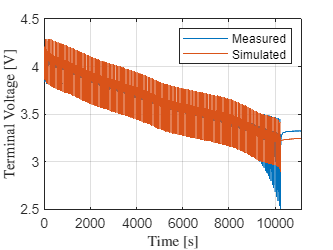


plot(Time, [Voltage, outputs]);
grid on;
legend('Measured', 'Simulated');
xlabel('Time [s]');
ylabel('Terminal Voltage [V]')
exportgraphics(gcf,'figures/ddp-macro.eps');

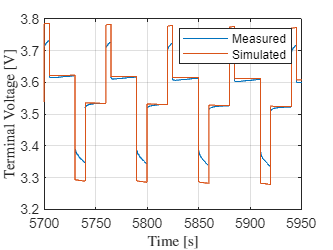

plot(Time, [Voltage, outputs]);
grid on;
legend('Measured', 'Simulated');
xlabel('Time [s]');
ylabel('Terminal Voltage [V]')
xlim([5700 5950]);
exportgraphics(gcf,'figures/ddp-detail.eps');

function [y, x_next] = ECM_1RC(x, u, Battery)
% Complete here 1RC ECM.
% Inputs u = [I]
% States x = [SOC; U1];
% Outputs y = [Ubat];
% Argument Battery - structure with parameters

SOC = x(1);
U1 = x(2);
I = u(1);

deltaT = 1;

% Battery parameters
Q = Battery.Q;
C1 = Battery.C1;
R1 = Battery.R1;
R0 = Battery.R0;
% Check sign of current - coulombic efficiency makes sense only charging.
if I > 0 % TODO check polarity of current
    eta = 1; % For discharging, efficiency is 1
else
    eta = Battery.eta;
end


%write discrete state equations
SOC_next = SOC - eta * deltaT / Q / 3600 * I;
U1_next = exp(-deltaT / R1 / C1) * U1 + R1 * (1 - exp(-deltaT / R1 / C1)) * I;
% TODO consider hysteresisoc

%compute actual OCV
Uocv = evaluate_Uocv(SOC, Battery);

%write output equation
Ubat = Uocv - I * R0 - U1;

%if necessary, format function outputs
y = Ubat;
x_next = [SOC_next; U1_next];
end

function [Time, Voltage, Current, Capacity] = extract_data(data)
    Time = seconds(duration(data.TotalTime, Inputformat="hh:mm:ss.SSS"));
    Time = Time - min(Time);
    Voltage = data.Voltage_V__V_;
    Current = -data.Current_A__A_;
    Capacity = data.Capacity_Ah__Ah_;
    
end

function rmse = calculate_error(y, yhat)
    rmse = sqrt(mean((y-yhat).^2));
end